data = load('ex2data2.txt');
X = data(:, [1, 2]); y = data(:, 3);


X = mapFeature(X(:,1), X(:,2))

X =     1.0000    0.0513    0.6996    0.0026    0.0359    0.4894    0.0001    0.0018    0.0251    0.3424    0.0000    0.0001    0.0013    0.0176    0.2395    0.0000    0.0000    0.0001    0.0009    0.0123    0.1675    0.0000    0.0000    0.0000    0.0000    0.0006    0.0086    0.1172
    1.0000   -0.0927    0.6849    0.0086   -0.0635    0.4691   -0.0008    0.0059   -0.0435    0.3213    0.0001   -0.0005    0.0040   -0.0298    0.2201   -0.0000    0.0001   -0.0004    0.0028   -0.0204    0.1508    0.0000   -0.0000    0.0000   -0.0003    0.0019   -0.0140    0.1033
    1.0000   -0.2137    0.6923    0.0457   -0.1479    0.4792   -0.0098    0.0316   -0.1024    0.3317    0.0021   -0.0068    0.0219   -0.0709    0.2296   -0.0004    0.0014   -0.0047    0.0152   -0.0491    0.1590    0.0001   -0.0003    0.0010   -0.0032    0.0105   -0.0340    0.1100
    1.0000   -0.3750    0.5022    0.1406   -0.1883    0.2522   -0.0527    0.0706   -0.0946    0.1266    0.0198   -0.0265    0.0355   -0.0475    0.0636   

initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147








% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

lambda = 0.01;
% Set Options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


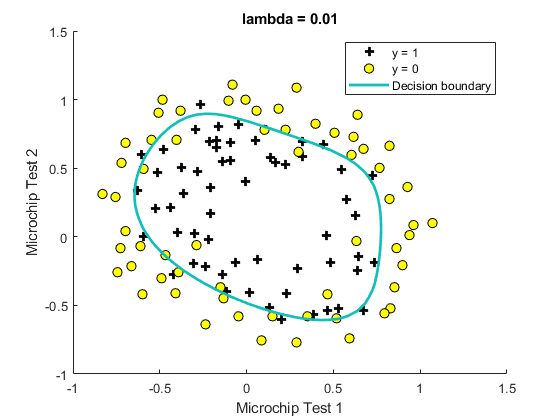

% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;


% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 83.898305
